% JSD Analysis
% Note double check images are the same between
% standard scenario 1 and alt. scenario 1 (scn 9)

%algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", "der"];
algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", "der"];
dataset = 'cifar10';

if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end

% Setup Figures
scn9_fig = figure(1);

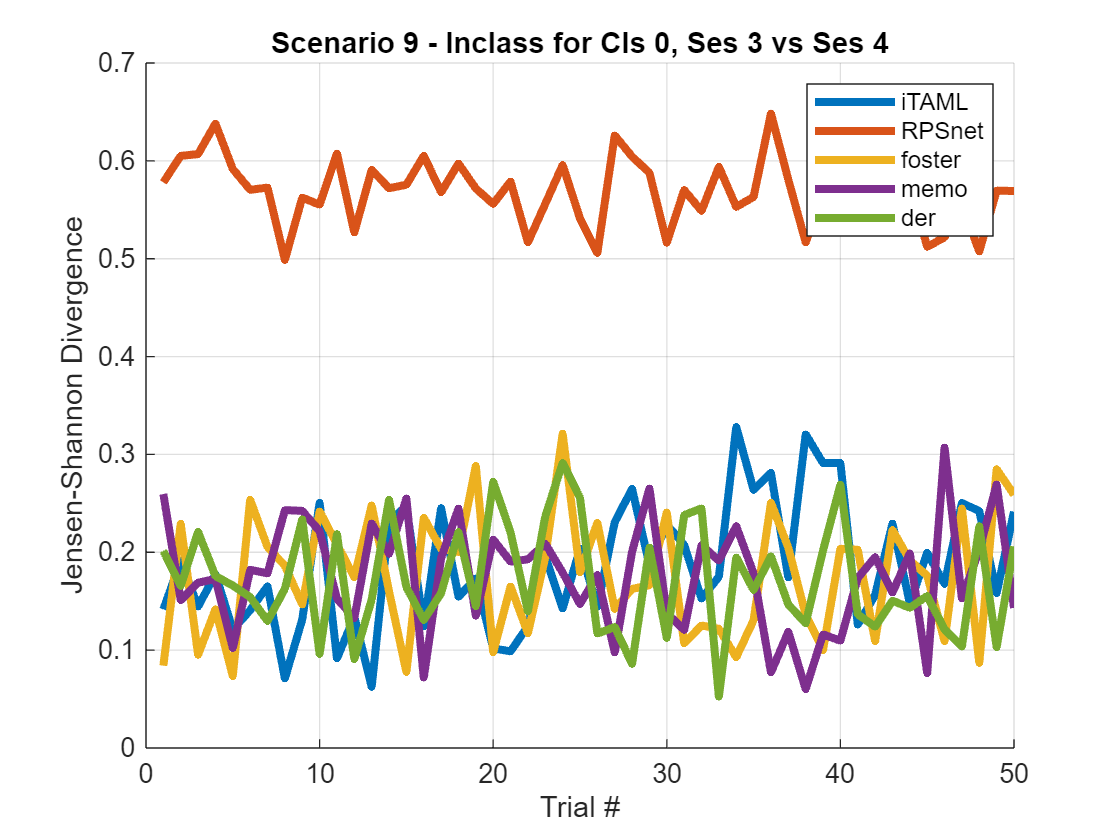

scn9_avgs =[];
scn9_stds = [];

for j=1:length(algs)
    jsd_struct = load(sprintf("%s\\%s\\inclass_jsd_alt.mat", algs(j), dataset));
    scn9_jsds = [];
    
    for i=1:length(fieldnames(jsd_struct))
        scn9_jsds = [scn9_jsds; getfield(jsd_struct, sprintf('t%d', i)).scn9];
    end

    % Plot JSDs
    figure(scn9_fig)
    hold on;
    plot(1:50, scn9_jsds, 'LineWidth', 3)
    title('Scenario 9 - Inclass for Cls 0, Ses 3 vs Ses 4');
    xlabel('Trial #');
    ylabel('Jensen-Shannon Divergence');
    grid on;

    % Calculate Averages and Std Devs
    scn9_avgs = [scn9_avgs; mean(scn9_jsds)];
    scn9_stds = [scn9_stds; std(scn9_jsds)];
end

figure(1)
legend(algs);
hold off;

% Create Table
scn9_table = table(scn9_avgs, scn9_stds, ...
    'VariableNames', ["Avg", "Std Dev"], 'RowNames', algs)

scn9_table = 5×2 table
                Avg      Std Dev 
              _______    ________

    iTAML     0.18653    0.064123
    RPSnet    0.56802     0.03506
    foster    0.17661    0.062651
    memo       0.1766    0.056144
    der       0.17204    0.055655


% Create JSD Table
%{
row_names = [];
for i=1:length(fieldnames(jsd_struct))
    row_names = [row_names; sprintf("Trial %d", i)];
end
scns = ["scn1", "scn2", "scn3", "scn4"];
jsd_table = table(scn1_jsds, scn2_jsds, ...
    'VariableNames', ["Scn 1", "Scn 2"], 'RowNames', row_names)
%}